# Classificação de Árvores e Matrizes Bottleneck

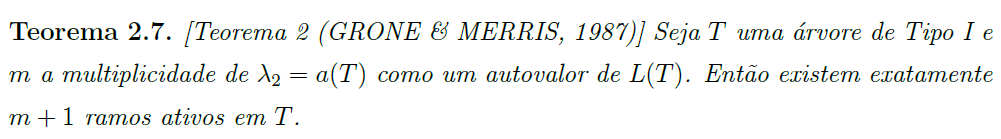

Definindo uma árvore do Tipo I e obtendo seu espectro

s=[1 3 3 5 5 7 7 9 5 10 12];
t=[2 2 4 4 6 6 8 8 10 11 11];
G=graph(s,t);

L=laplacian(G);
L=full(L);
[u,v]=eigs(L,size(L,1));

Note que a multiplicidade algébrica de a(T)=1, logo temos m+1 ramos ativos em T.

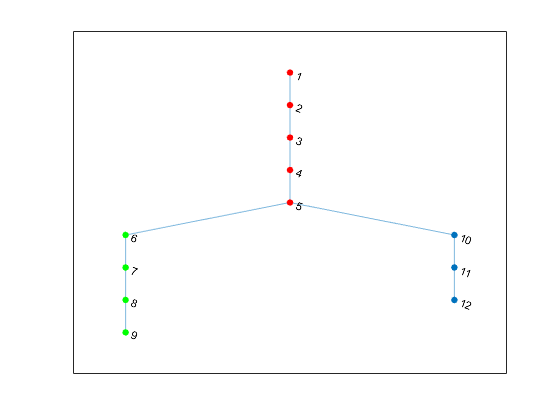

p=plot(G);
highlight(p, [1:5], 'NodeColor', 'r')
highlight(p, [6:9], 'NodeColor', 'g')

Os ramos em vermelho e verde são ativos, e o ramo em azul é passivo.

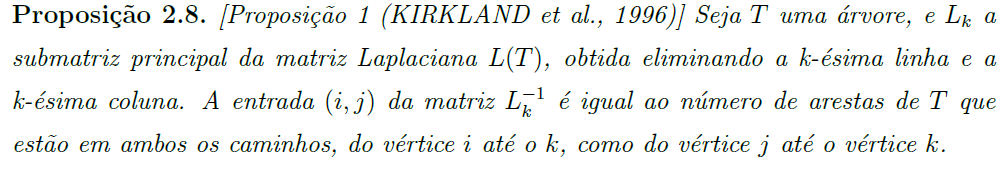

Definindo uma árvore do Tipo II e obtendo seu espectro:

s=[1 3 4 5 5 7 7 7 9 11];
t=[2 2 2 2 6 5 8 9 10 9];
G=graph(s,t);
h=plot(G);
L=laplacian(G);
L=full(L);
[u,v]=eigs(L,size(L,1));

Vamos escolher a linha e a coluna correspondente ao vértice k e inverter a matriz L:

k=5

k = 5

L(k,:)=[];
L(:,k)=[];

Linverse=inv(L);

Vamos escolher i e j:

i=6

i = 6

j=6

j = 6

disp(['Número de arestas de T que estão em ambos os caminhos, ' ...
    'do vértice i até k, e do vértice j até k.'])

Número de arestas de T que estão em ambos os caminhos, do vértice i até k, e do vértice j até k.


display(Linverse(i,j))

     1



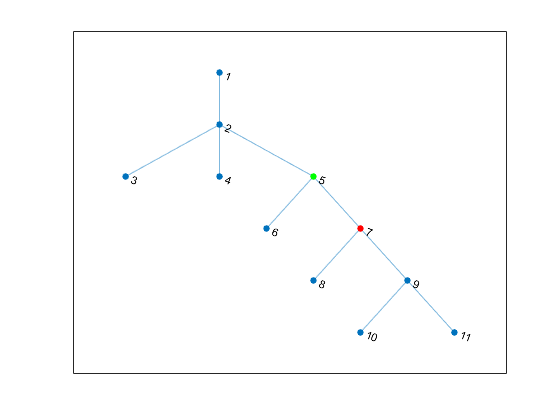

highlight(h, [i+1,j+1], 'NodeColor', 'r')
highlight(h, k, 'NodeColor', 'g')

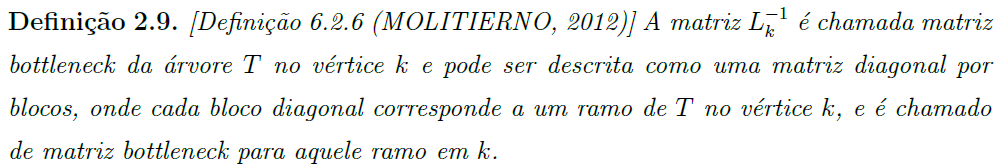

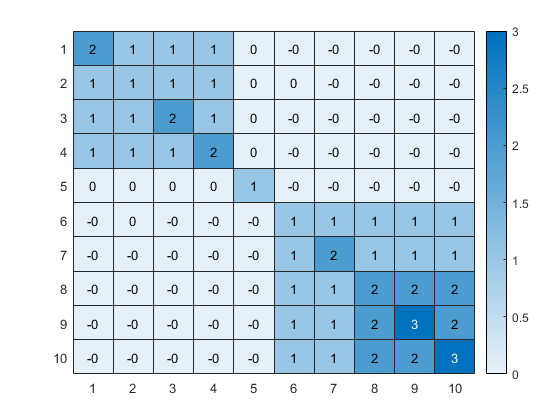

ans =   HeatmapChart with properties:

        XData: {10×1 cell}
        YData: {10×1 cell}
    ColorData: [10×10 double]

  Show all properties


heatmap(Linverse)